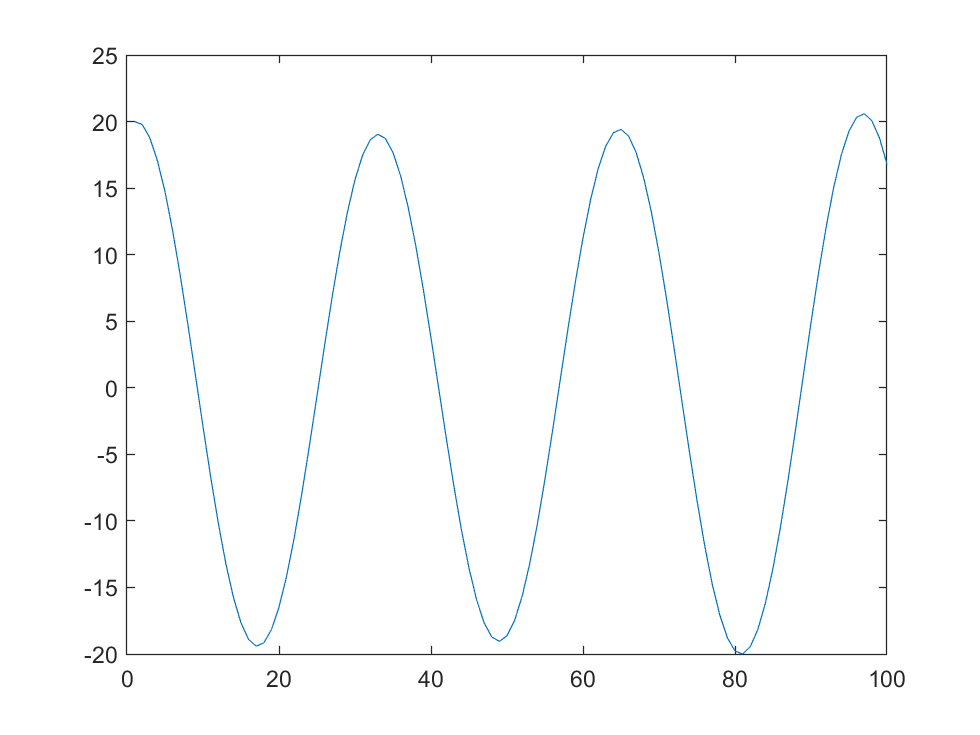

%ECOMMS Lab Project 1 Example 
%Dawson Tocarchick, Kyle Limbaga, Michael Johns
%Rowan University 
%This program generates a 1-second duration  
%Asharp signal (466.16 Hz) with a specified SNR

%Specify SNR 
snr=10; 

%Generate Asharp signal
t=[0:1/8e3:1.0]';

A_c = 20;
f_m = 200;
f_c = 250;
b = 1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Different Waveforms     %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%s = 0.5*sin(2*pi*466.16*t);
%s = A_c*[1+cos(2*pi*f_m*t)].*(cos(2*pi*f_c*t));
s = A_c*cos(2*pi*f_c*t) + b*sin(2*pi*f_m*t);

plot(s);
xlim([0 100]);

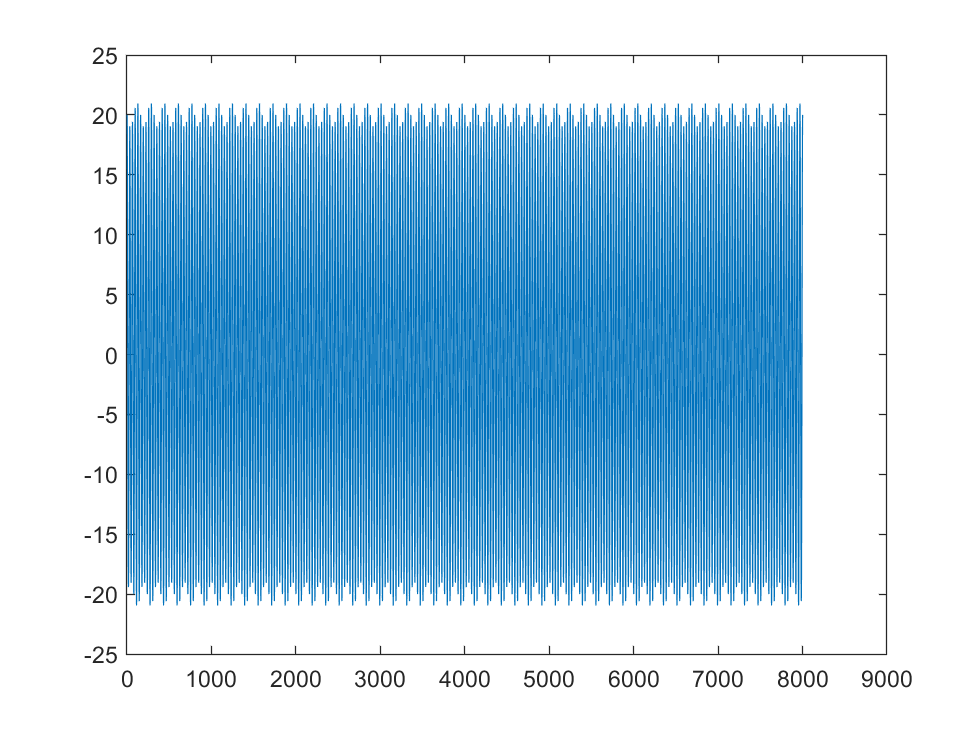


%sound(s); 

%Compute signal variance 
var_s = cov(s);

%Calculate required noise variance 
var_noise=var_s/(10^(snr/10)); 

%Generate noise 
n=sqrt(var_noise)*randn(length(s),1); %sound(n);

%Add signal to noise and generate message 
m=s+n; %sound(m); 

plot(s);

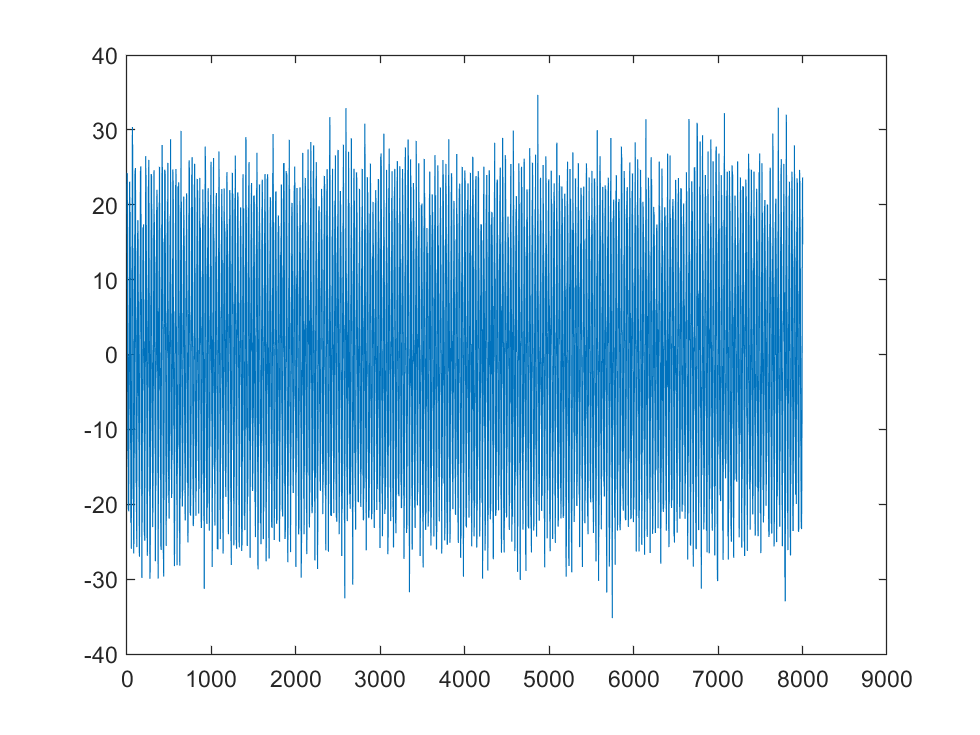

plot(m);

part 2:

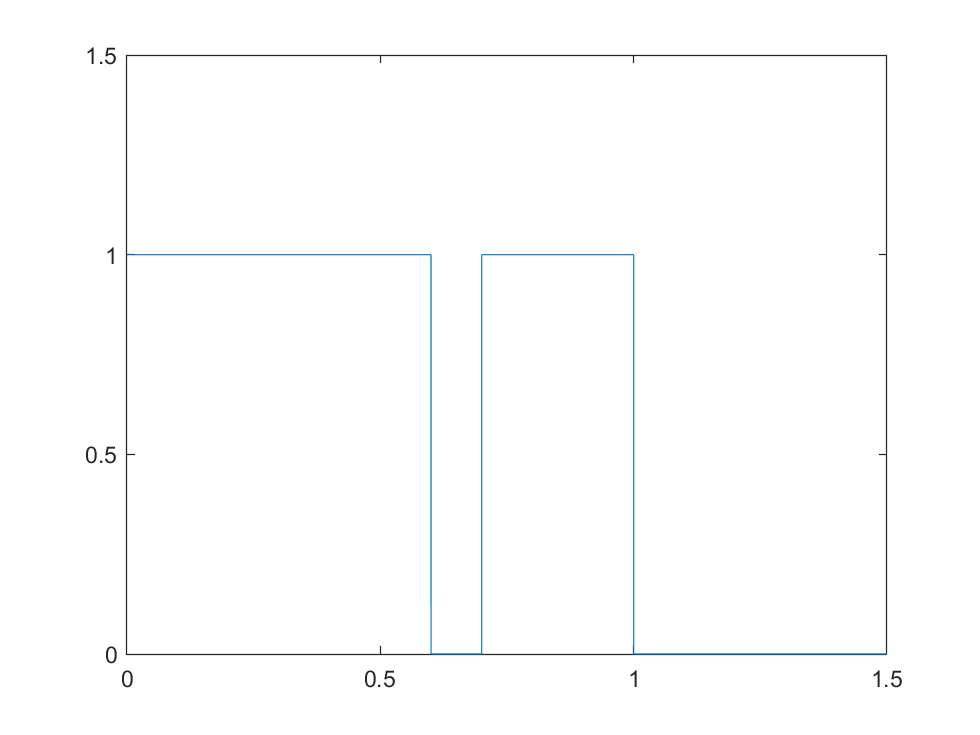

% syms x;
% fplot(heaviside([x-1;x]), [-2,2])

syms y(x)
y(x) = rectangularPulse(0,0.6,x)+rectangularPulse(0.7,1,x);

figure(1);
fplot(y);
axis([0 1.5 0 1.5]);

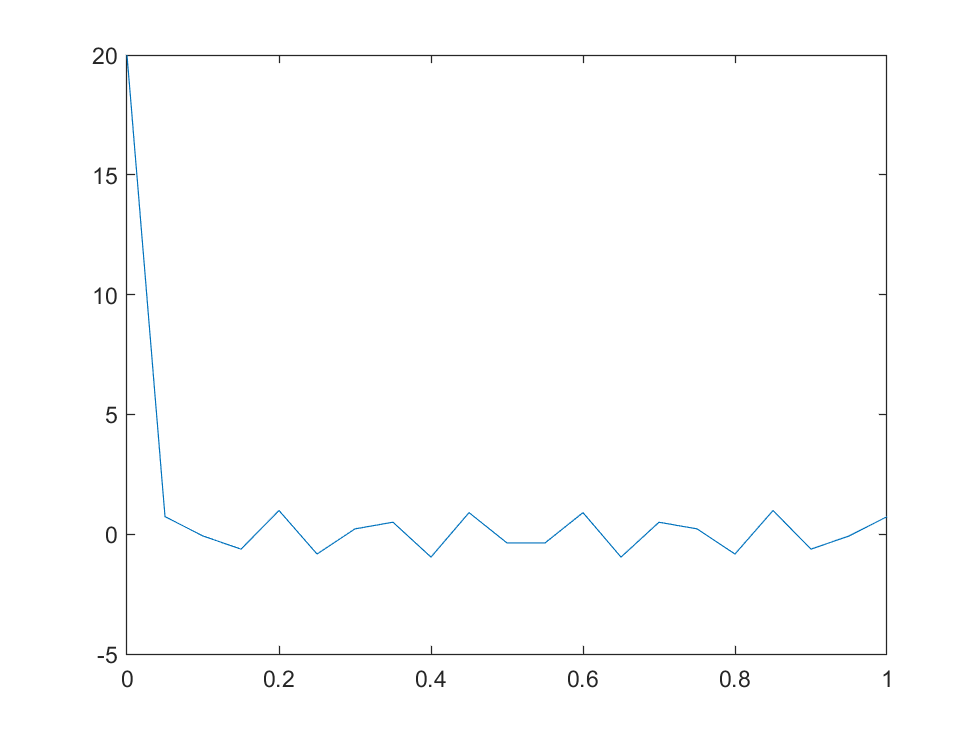


figure(2);
plot([0:0.05:1],fft(double(y([0:0.05:1]))));

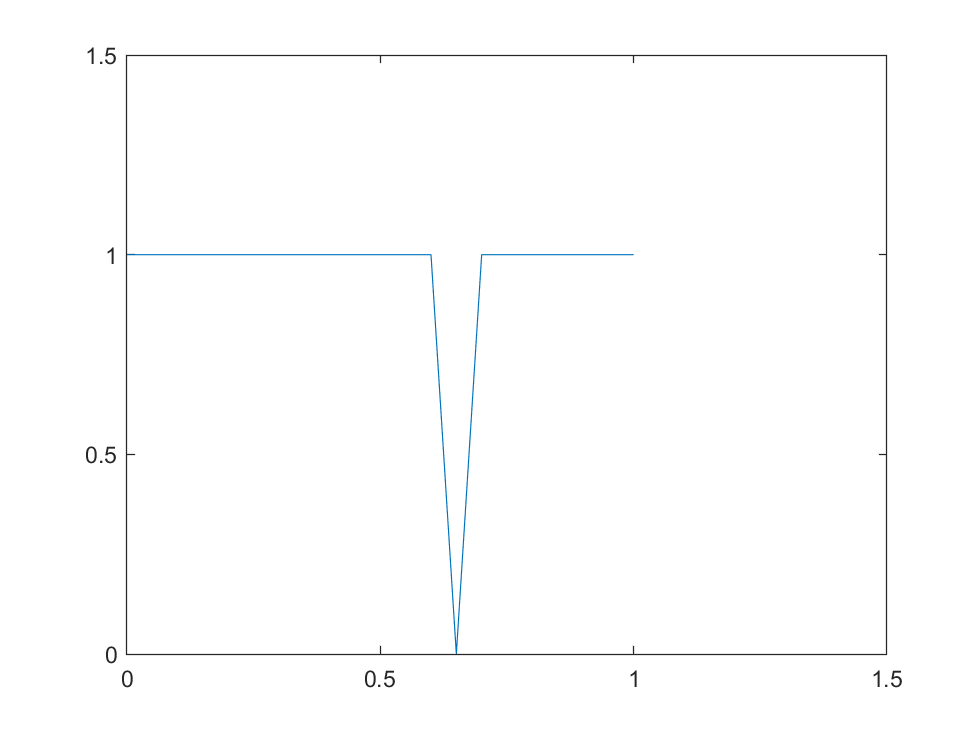


figure(3);
plot([0:0.05:1],ifft(fft(double(y([0:0.05:1])))));
axis([0 1.5 0 1.5]);

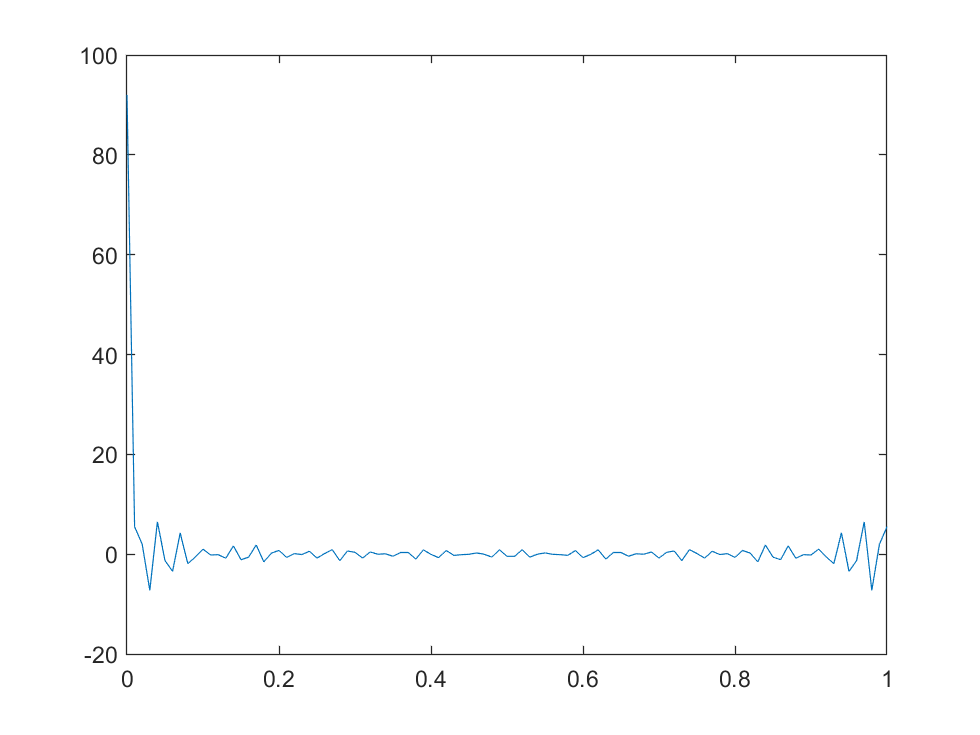


figure(4);
plot([0:0.01:1],fft(double(y([0:0.01:1]))));

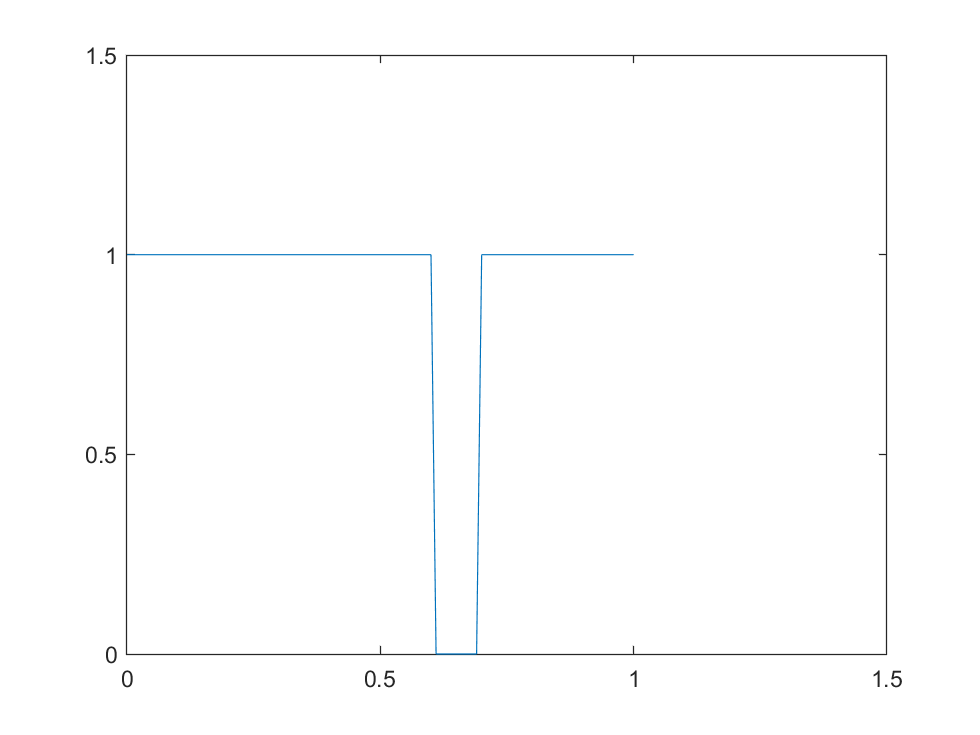


figure(5);
plot([0:0.01:1],ifft(fft(double(y([0:0.01:1])))));
axis([0 1.5 0 1.5]);

ADDED STUFF BY DAWSON, TESTING OUT THINGS WITH SONGS


song = audioread('For_Love.mp3');
%sound(song, 44100)

fft(song)

ans = 	1.0e+05 *

   0.0251 + 0.0000i  -0.0048 + 0.0000i
  -0.0047 - 0.0027i  -0.0007 + 0.0013i
  -0.0021 - 0.0042i   0.0001 + 0.0011i
  -0.0021 - 0.0018i   0.0031 + 0.0028i
  -0.0027 - 0.0032i  -0.0016 - 0.0006i
   0.0010 - 0.0018i  -0.0013 - 0.0016i
  -0.0017 + 0.0048i   0.0002 - 0.0003i
   0.0001 + 0.0003i  -0.0012 + 0.0007i
   0.0004 + 0.0001i   0.0004 + 0.0002i
  -0.0025 + 0.0012i  -0.0026 + 0.0004i


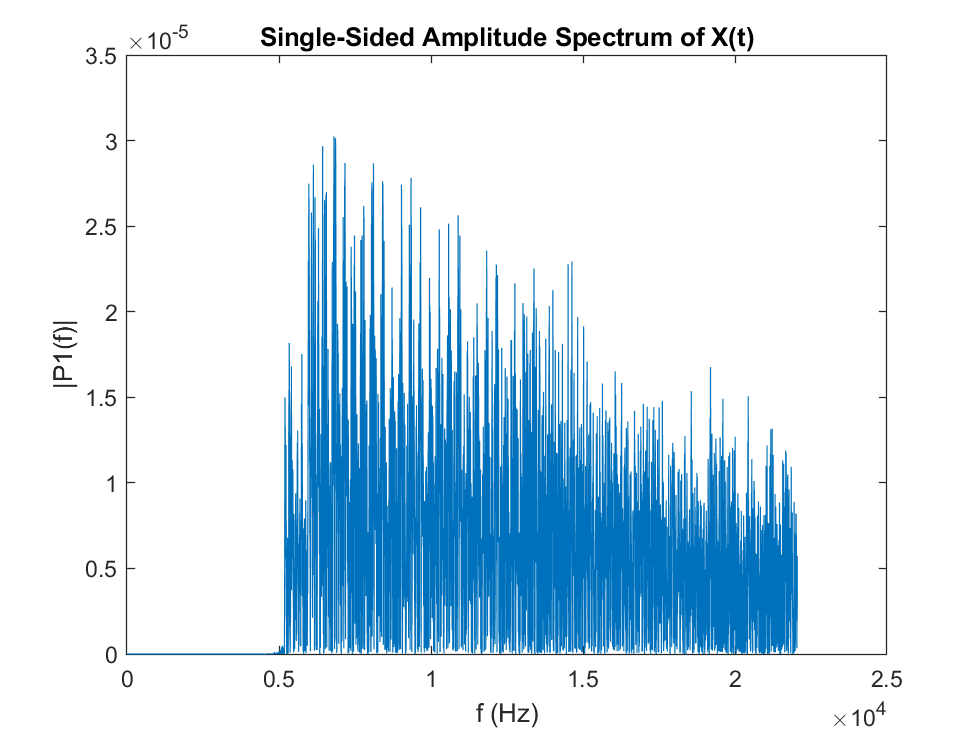

Fs = 44100;
T = 1/Fs;             % Sampling period       
L = 60000;             % Length of signal
t = (0:L-1)*T;        % Time vector

P2 = abs(song/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

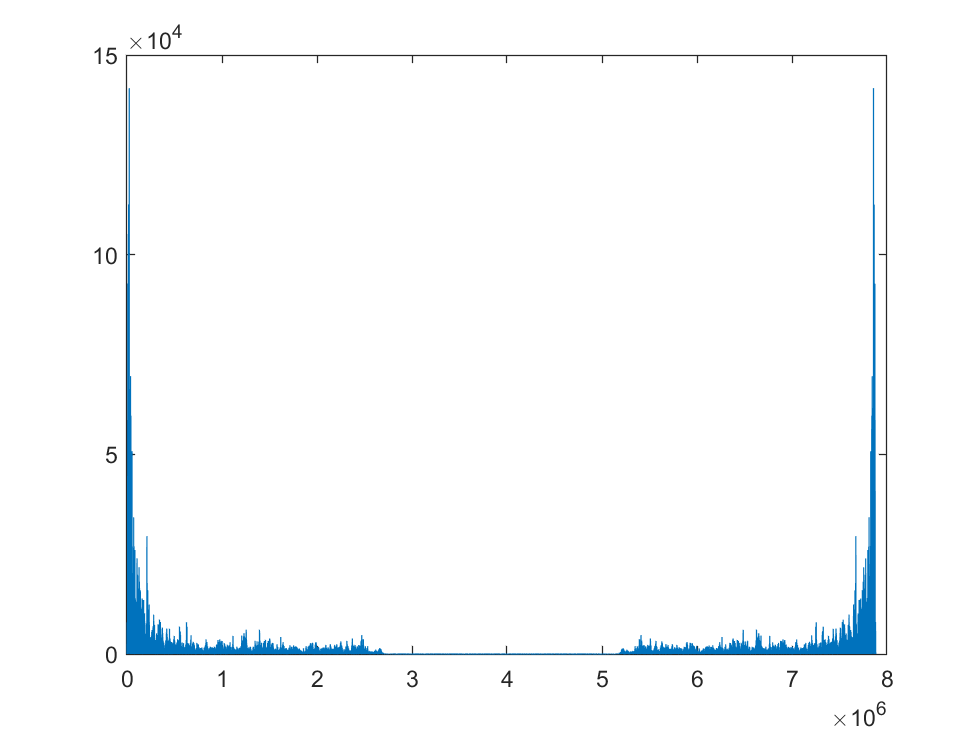



[data, fs] = audioread('For_Love.mp3');
data_fft = fft(data);
plot(abs(data_fft(:,1)))